# 3D Voronoi Network Generator

% Copyright (c) 2020 Shiyu Liu. All rights reserved.

clc
clear
close all

% 'length_cube': the edge length of the cube space
length_cube=300;

% define the cube space
Xa=1;
Ya=1;
Za=1;

% 'num_seeds': total number of seeds.
% 'devi': deviation of seed locations from original site.
num_seeds=100;
devi=0;

% 'Vcub': coordinates of cube's vertices
% Vcub(:,2)=2*Vcub(:,2); -- you can extrude the cube like this
% It is OK to have out-of-boundary seed points.
Vcub=length_cube*[0 0 0; Xa 0 0; 0 Ya 0; 0 0 Za;
    Xa Ya Za; 0 Ya Za; Xa 0 Za; Xa Ya 0];

% 'seeds': 3D coordinate of all seeds.
% rand(m,n) returns a m-by-n matrix of random entries.
% each element of rand(m,3) is within [1 1 1]
seeds=length_cube*(rand(num_seeds,3)-devi);

% 'Ver'：3D coordinate of cells' vertices
% 'Cel'：each cell is recorded as a set of mark numbers of its vertices.

% C_tst return 0 if the cell is outside the box, 1 if it has been...
% untouched from the original voronoin(seeds) function, 2 if it has...
% been cut by the edges of the box.
[Ver,Cel,C_tst]=voronoi3d_cuboid(seeds,Vcub);

## Visualization of 3D Voronoi Cuboid

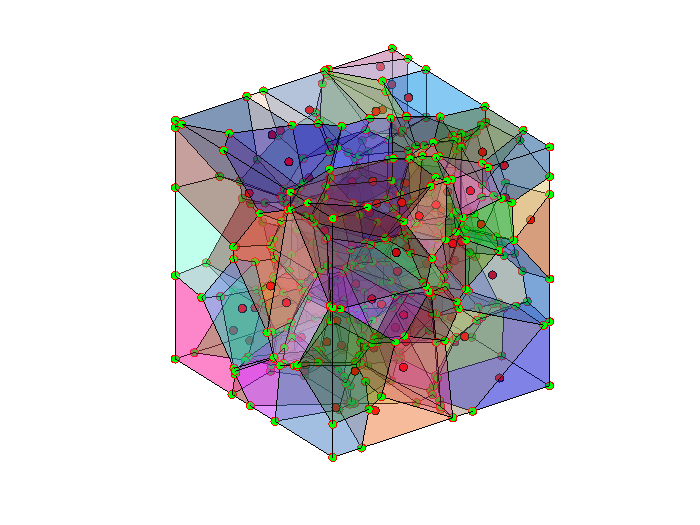

h=figure;
ax = axes('Parent',h);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';

hold on
axis('equal')
view([-36 27])
scatter3(seeds(:,1),seeds(:,2),seeds(:,3),25, ...
    'Marker','o','MarkerFaceColor',[1 0 0], 'MarkerEdgeColor','k');
scatter3(Ver(:,1),Ver(:,2),Ver(:,3),25, ...
    'Marker','o','MarkerFaceColor',[0 1 0], 'MarkerEdgeColor','r');

for k = 1:length(Cel)
    if ~isempty(Cel{k})
        col=rand(1,3);
        Vk = Ver(Cel{k},:); Fk = convhull(Vk);
        if exist('mergeCoplanarFaces.m','file')==2
            [Vk, Fk] = mergeCoplanarFaces(Vk, Fk);
            for i=1:length(Fk)
                patch('Vertices',Vk,'Faces',Fk{i},'FaceColor',col,'FaceAlpha',0.3)
            end
        else
            trisurf(Fk,Vk(:,1),Vk(:,2),Vk(:,3),'FaceColor',col, ...
                'FaceAlpha', 1,'EdgeAlpha',1,'EdgeColor','k')
        end
    end
end
xlabel('X');ylabel('Y');zlabel('Z');

## 3D Voronoi Network Generation

% 'Vnet': lines of network represented by its two vertices
Vnet=[];V1=[];V2=[];

for k = 1:length(Cel)
    if ~isempty(Cel{k})
        %'Vk': all vertices of Cell k
        Vk = Ver(Cel{k},:);
        %'Fk': all faces of conv Cell k
        Fk = convhull(Vk);
        
        % if tri surfaces can be merged into polygons
        if exist('mergeCoplanarFaces.m','file')==2
            [Vk, Fk] = mergeCoplanarFaces(Vk, Fk);
            
            for i = 1:length(Fk)
                % if Fk(i) is on the outer surface, then drop it
                TOS=false;
                V1=Vk(Fk{i}(1),:); V2=Vk(Fk{i}(2),:);
                % note that 'Fk' is a Cell Array,
                % 'Fk{i}' is a nx1 Array
                for l=1:3
                    if ((V1(l)==0)&&(V2(l)==0)) ||...
                            ((V1(l)==Vcub(5,l))&&(V2(l)==Vcub(5,l)))
                        TOS=true;
                        break
                    end
                end
                
                % add all edges of Fk{i} into Vnet
                if ~TOS
                    for j = 1:(length(Fk{i})-1)
                        Vnet = [Vnet;Vk(Fk{i}(j),:),Vk(Fk{i}(j+1),:)];
                    end
                    Vnet = [Vnet;Vk(Fk{i}(j+1),:),Vk(Fk{i}(1),:)];
                end
            end
            
            % if tri surfaces cannot be merged into polygons
        else
            for i = 1:length(Fk)
                % if Fk(i) is on the outer surface, then drop it
                TOS=false;
                V1=Vk(Fk(i,1),:); V2=Vk(Fk(i,2),:);
                % note that 'Fk' is a Cell Array,
                % 'Fk{i}' is a nx1 Array
                for l=1:3
                    if ((V1(l)==0)&&(V2(l)==0)) ||...
                            ((V1(l)==Vcub(5,l))&&(V2(l)==Vcub(5,l)))
                        TOS=true;
                        break
                    end
                end
                
                % add all edges of Fk{i} into Vnet
                if ~TOS
                    Vnet = [Vnet;Vk(Fk(i,1),:),Vk(Fk(i,2),:)];
                    Vnet = [Vnet;Vk(Fk(i,2),:),Vk(Fk(i,3),:)];
                    Vnet = [Vnet;Vk(Fk(i,3),:),Vk(Fk(i,1),:)];
                end
            end
        end
    end
end

% remove repeating lines
Vnet=unique(Vnet,"rows");

filenameNOW=['Voronoi3D_',datestr(now,30),'.mat'];
save(filenameNOW);